# Forced damped Pendulum

First, for a samplling of values of the parameter $A$, we plot simulations. We take samples of the solution once per period of the forcing using the *events location* feature of `ode45`.

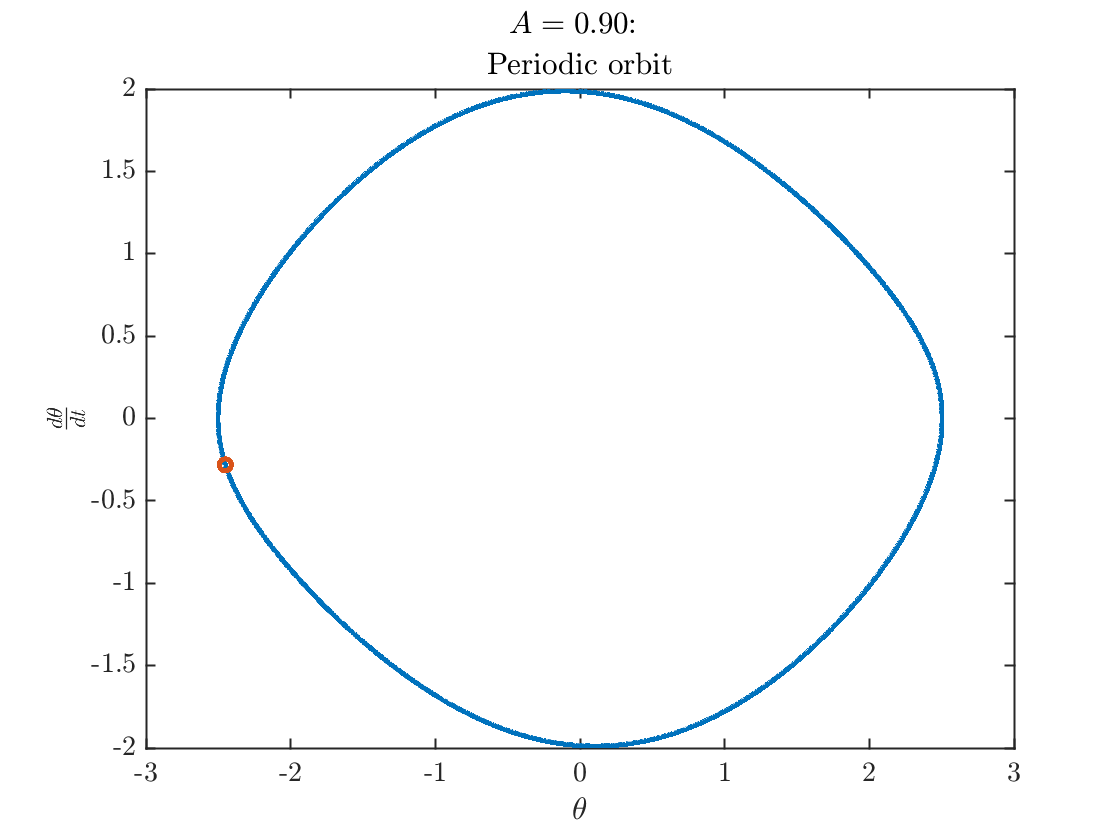

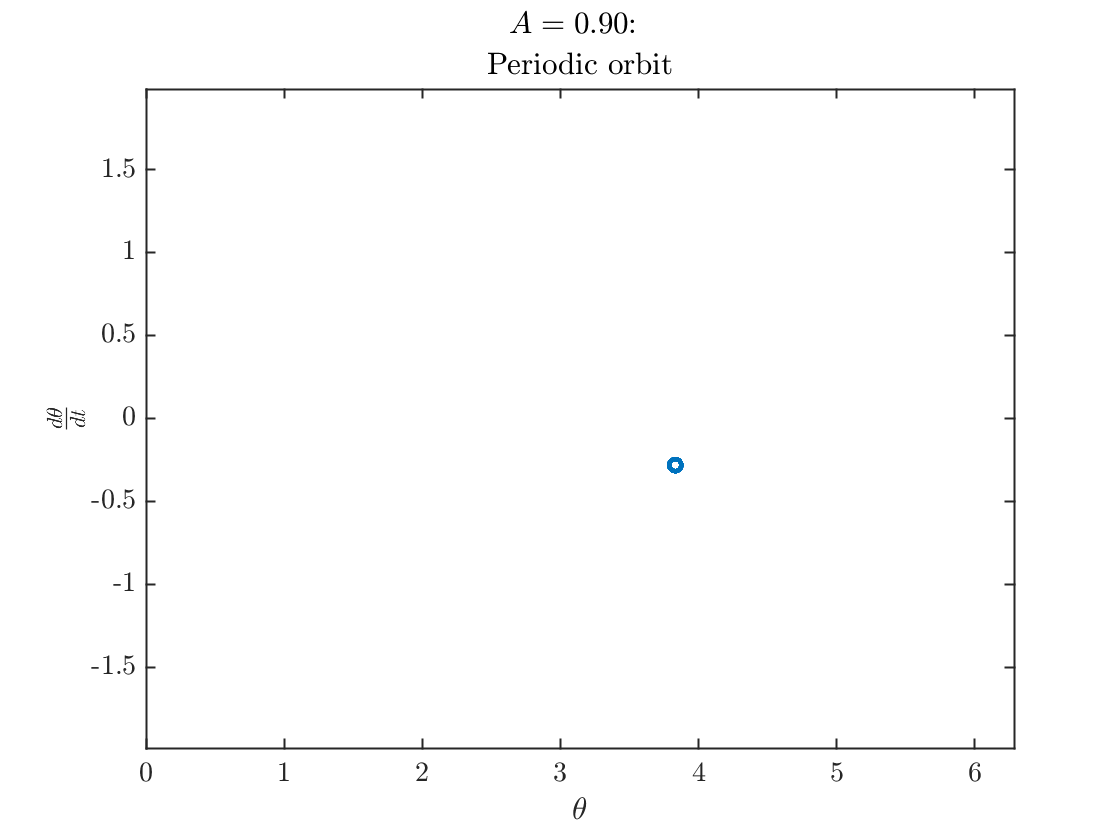

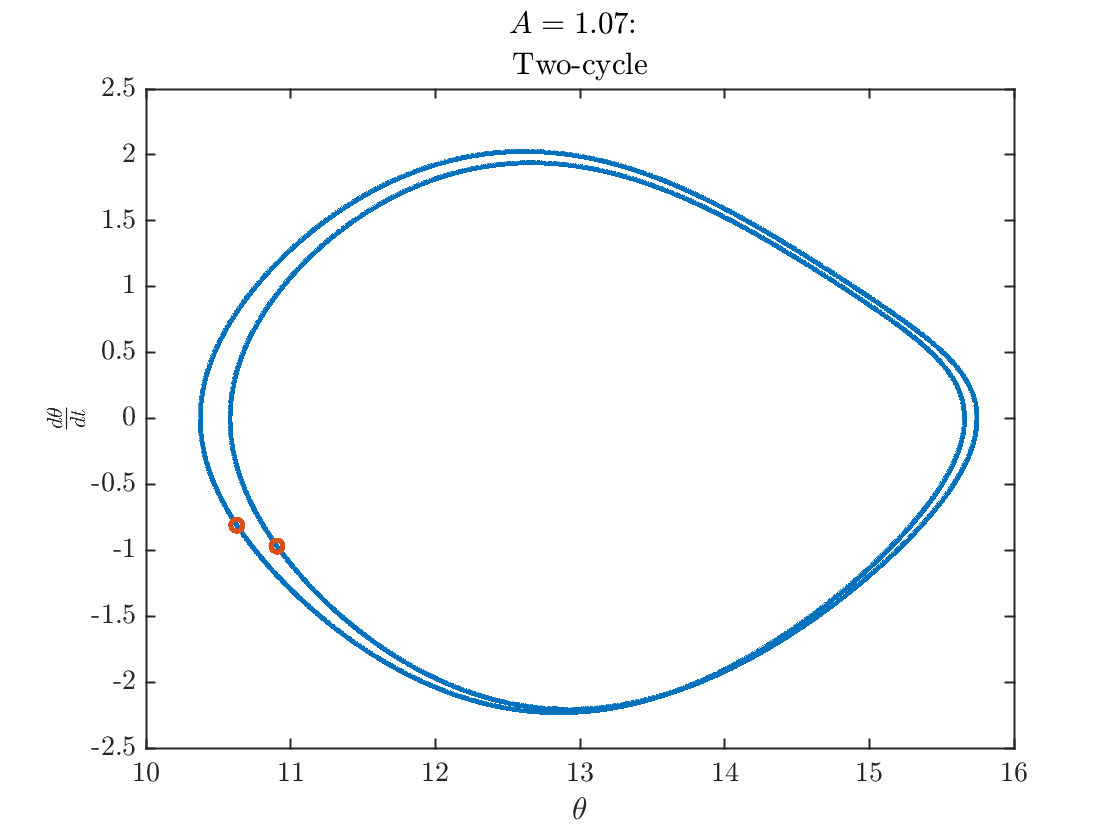

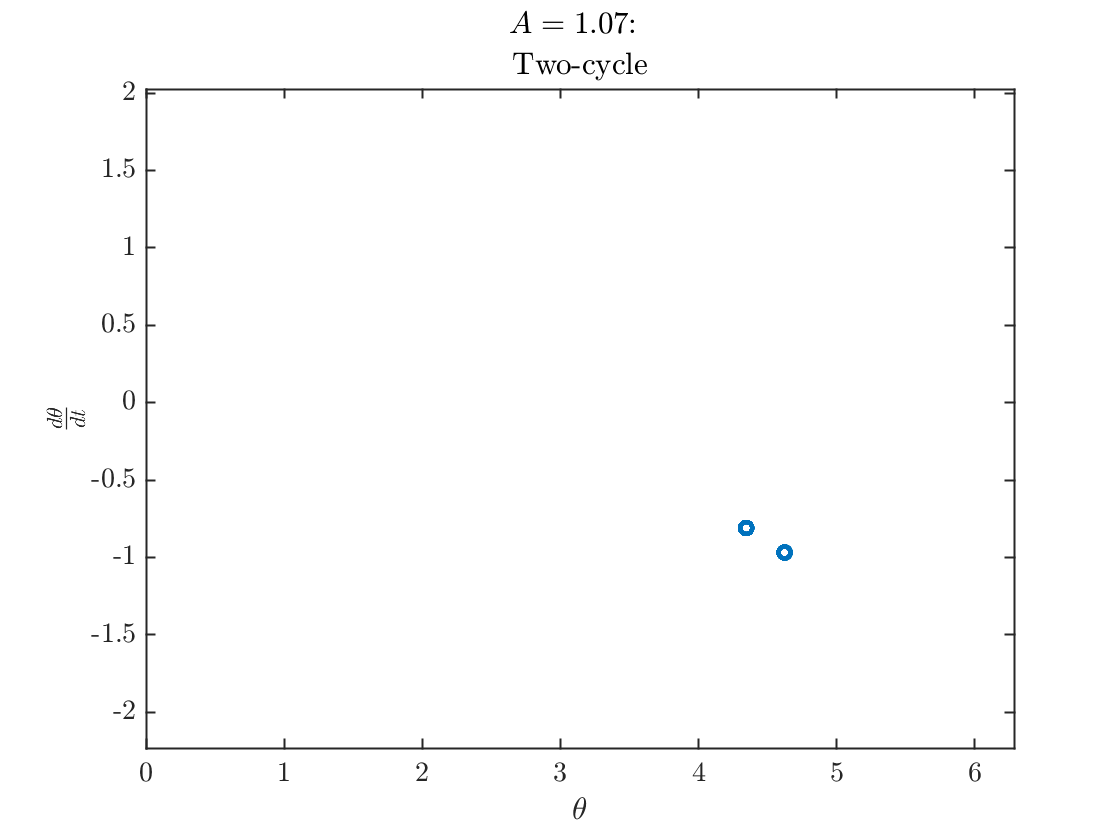

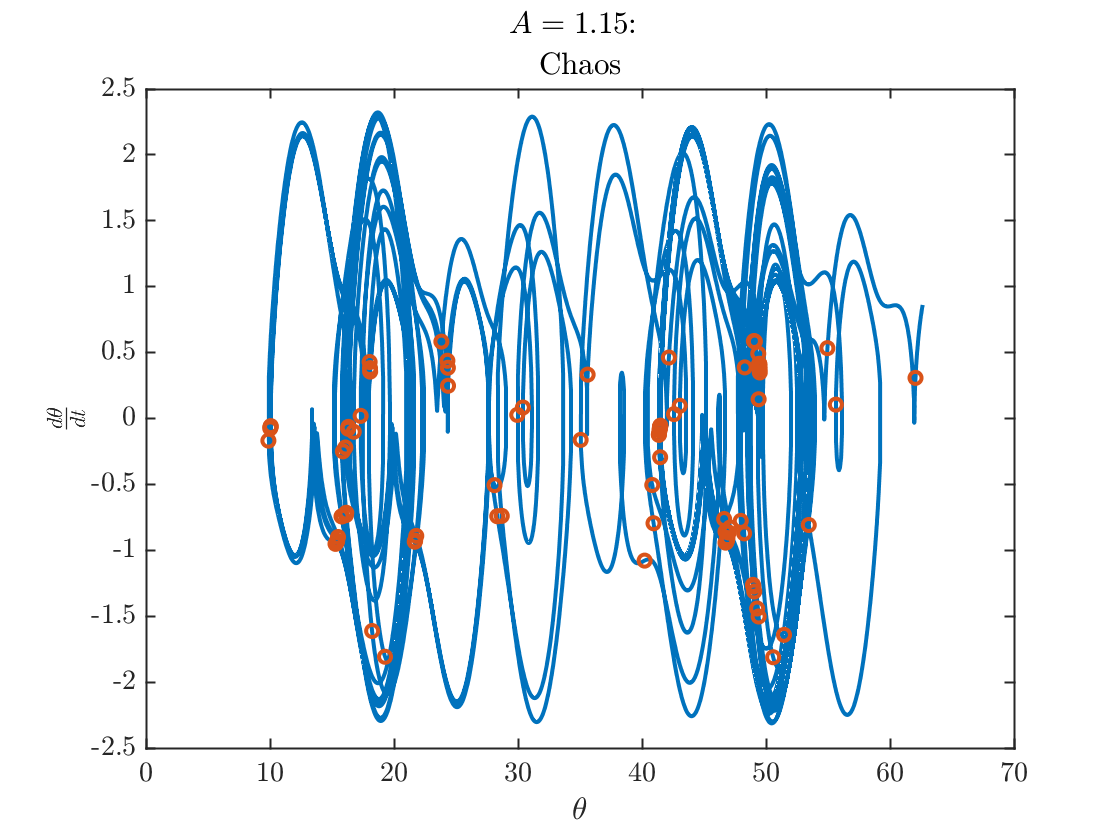

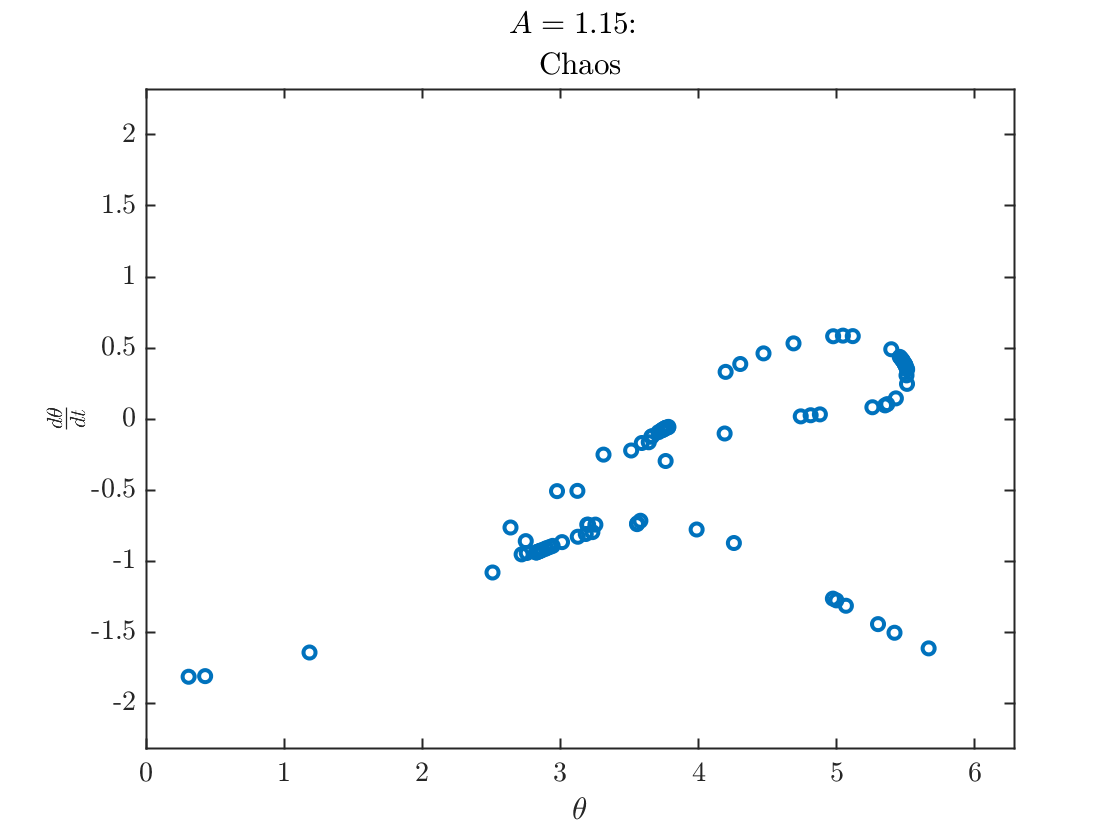

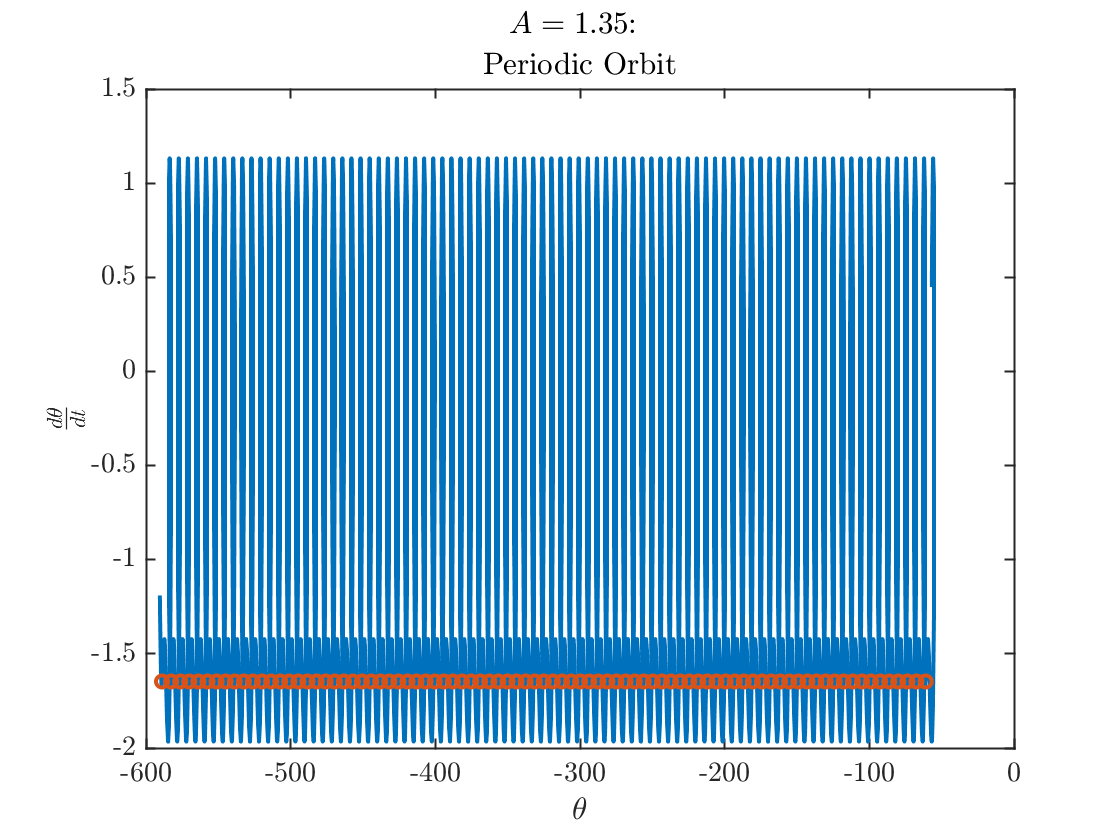

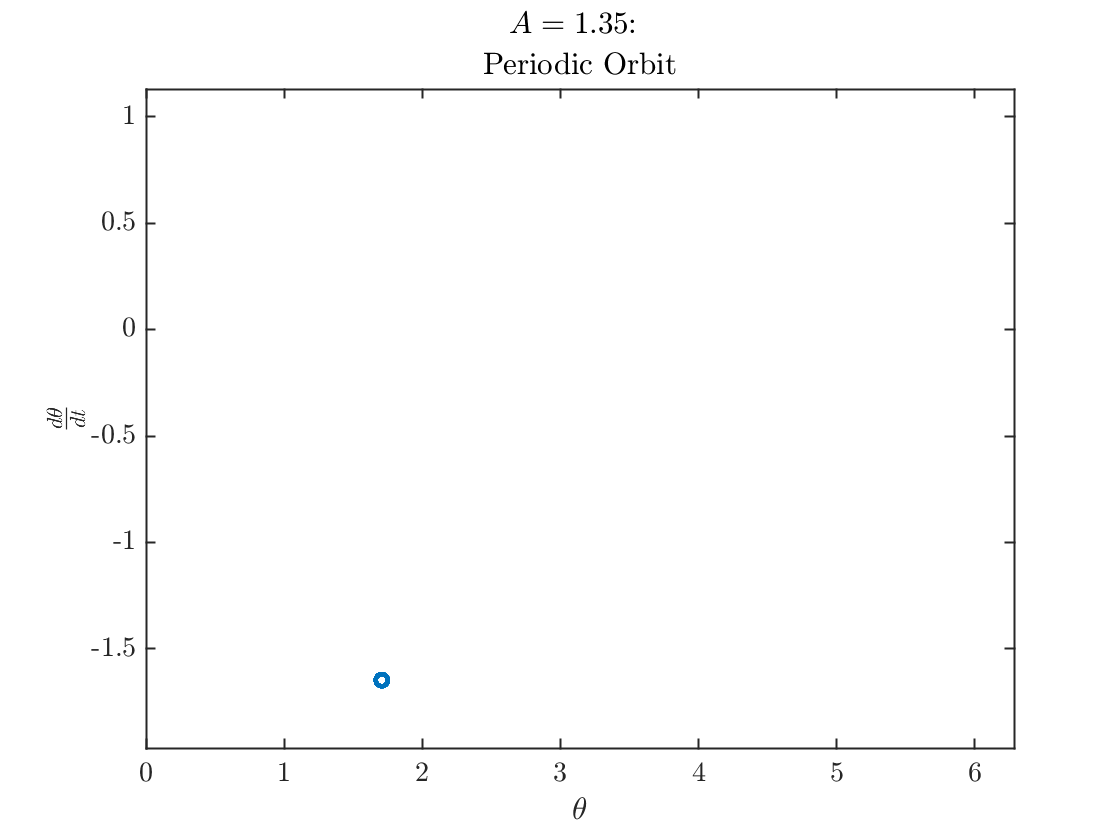

b=1/2;
omega=2/3;
A_vector=[0.9 1.07 1.15 1.35 1.46 1.5];
behaviors=["Periodic orbit","Two-cycle","Chaos","Periodic Orbit","Four-cycle","Chaos"];
nA=length(A_vector);
y0=[0 1];
tSpan=[0 1000];
tTransient=200;

for k=1:nA
    A=A_vector(k);
    f=@(t,y)pendForceDamp(t,y,b,A,omega);
    fEvent=@(t,y)pendulumEvent(t,y,omega);
    options=odeset('Events',fEvent,'RelTol',1e-8,'AbsTol',1e-8);
    [t,y,te,ye]=ode45(f,tSpan,y0,options);
    % Throw away a transient
    spot=find(t>tTransient,1,'first');
    y=y(spot:end,:);
    % Throw away a transient from the events time series
    spot=find(te>tTransient,1,'first');
    ye=ye(spot:end,:);
    figure
    plot(y(:,1),y(:,2),ye(:,1),ye(:,2),'o')
    title(sprintf('$A=%0.2f$: %s',A),behaviors(k))
    xlabel('$\theta$');ylabel('$\frac{d\theta}{dt}$')
    
    figure
    plot(mod(ye(:,1),2*pi),ye(:,2),'o')
    axis([0 2*pi min(y(:,2)) max(y(:,2))])
    title(sprintf('$A=%0.2f$: %s',A),behaviors(k))
    xlabel('$\theta$');ylabel('$\frac{d\theta}{dt}$')
    
    y0=y(end,:); % use the final solution as the new initial condtion
end

## Bifurcation Diagram

Here we see some period-doubling but we do not see a diagram equivalent to the logistic map.

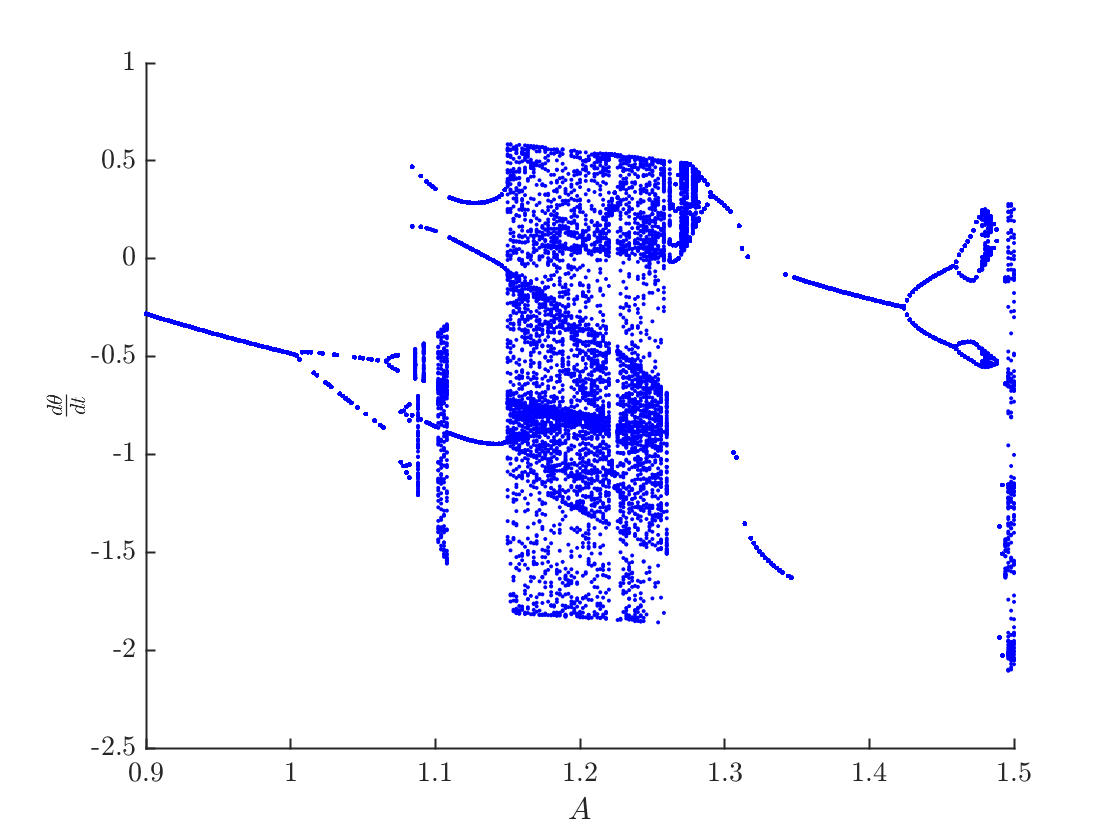

nA=301;
a0=0.9;
a1=1.5;
A_vector=linspace(a0,a1,nA);
tSpan=[0 2000];
tTransient=1000;

figure;clf;hold on;
for k=1:nA
    A=A_vector(k);
    f=@(t,y)pendForceDamp(t,y,b,A,omega);
    fEvent=@(t,y)pendulumEvent(t,y,omega);
    options=odeset('Events',fEvent,'RelTol',1e-8,'AbsTol',1e-8);
    [~,~,te,ye]=ode45(f,tSpan,y0,options);
    % Throw away a transient from the events time series
    spot=find(te>tTransient,1,'first');
    ye=ye(spot:end,:);
    plot(ones(length(ye),1)*A,ye(:,2),'b.')
end
xlabel('$A$');ylabel('$\frac{d\theta}{dt}$')

## Functions called

function dydt=pendForceDamp(t,y,b,A,omega)
dydt=zeros(2,1);
dydt(1) = y(2);
dydt(2) = -b* y(2) - sin(y(1)) + A*sin(omega*t);
end

function  [value, isterminal,direction]=pendulumEvent(t,~,omega)
value= sin(omega*t);
isterminal = 0;
direction = 1;
end